# Chicken Ballistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 2

Solve the system of ODEs. 

tRange = [0 3];
Y0 = [0; 20];
[tSol, YSol] = ode45(@chicken, tRange, Y0);

## Task 3

Extract and plot the height.

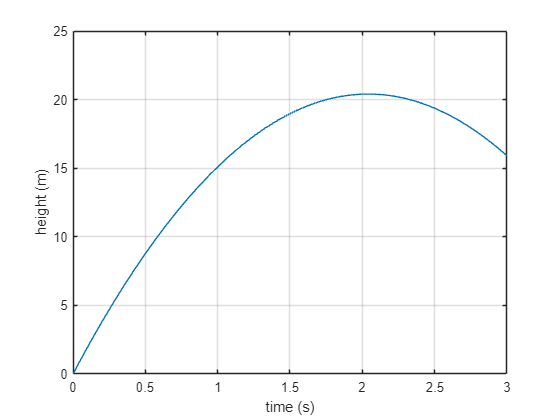

h = YSol(:, 1);
plot(tSol, h)
grid on
xlabel('time (s)')
ylabel('height (m)')

ODE functions do not need to be local functions; you can also write an ODE function file.

The syntax to define the function is identical. When you save the file, the filename must match the function name.

function dYdt = chicken(t, Y)
    % TODO - Extract the height h from input vector Y
    h = Y(1);
    
    % TODO - Extract the velocity u from input vector Y
    u = Y(2);
    
    % TODO - Complete expression for dhdt
    dhdt = u;
    
    % TODO - Complete expression for dudt
    dudt = -9.8;
    % TODO - Define output column vector dYdt
    dYdt = [dhdt; dudt];
end